# Stereocamera more advanced calculations

### Secondary questions

Now that we hav enarrowed down a sensor and have the necessary values for some of the things we need, we can now calculate the exact values for the particles in terms of size and such. We also now do stereo-size calculations as well as lighting calculations.

#### The Camera Specifications

%use the sensor for the ras pi HQ camera for about $50
camera = struct('name',"raspi HQ cam",'fov',[63,63],'focal_distance',6e-3,'resolution',[4056,3040],'sensor_size',[6.287,4.712]*1e-3,'pixel_size',1.55e-6,'f_stop',8);

%camera = struct('name',"raspi cam v2",'fov',[62.2,62.2],'focal_distance',3.04e-3,'resolution',[3280,2464],'sensor_size',[3.68,2.76],'pixel_size',1.12e-6,'f_stop',2.0);

%modify the camera fov values and the apparent focal distance based on the
%water refractive properties
%camera fov
camera.fov(1) = camera.fov(1)/1.33;
camera.fov(2) = camera.fov(2)/1.33;

%camera apparent focal length
camera.focal_distance = camera.sensor_size(2)/(2*tand(camera.fov(2)*0.5));

%show the camera stats
camera

camera = struct with fields:
              name: "raspi HQ cam"
               fov: [47.3684 47.3684]
    focal_distance: 0.0054
        resolution: [4056 3040]
       sensor_size: [0.0063 0.0047]
        pixel_size: 1.5500e-06
            f_stop: 8


#### The Particle Specifications

%particle sizes in m (so actually measured in micrometers)
particleSizes = [20, 50, 100, 200:200:2000]*1e-6;

%particle speeds (smaller particles will be slower)
particleSpeeds = [25, 50, 100, 200:200:2400]*1e-6;

%mesoplankton density (or large object density) per cubic meter
%200-2000 micrometers
mesoDensity = 1.3e3;

%phytoplankton density (or small object density) per cubic meter
%50-200 micrometers
phytoDensity = 1.3e5;

%particle distances from camera - start imaging at 8 cm at the absolute
%minimum and 0.75m at the ABSOLUTE maximum value
particleDistances = [8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20:5:75]*1e-2;

#### Calculate the Particle pixel size we expect at various distances

%the equation in question is:
%object height(pix) = [focus distance*real height*image height]/[distance
%to object*sensor height]
syms pixHeight focDist realHeight imgHeight distObj sensorHeight
linSize = (focDist*realHeight*imgHeight)/(distObj*sensorHeight)

$$linSize = \frac{\mathrm{focDist}\,\mathrm{imgHeight}\,\mathrm{realHeight}}{\mathrm{distObj}\,\mathrm{sensorHeight}}$$

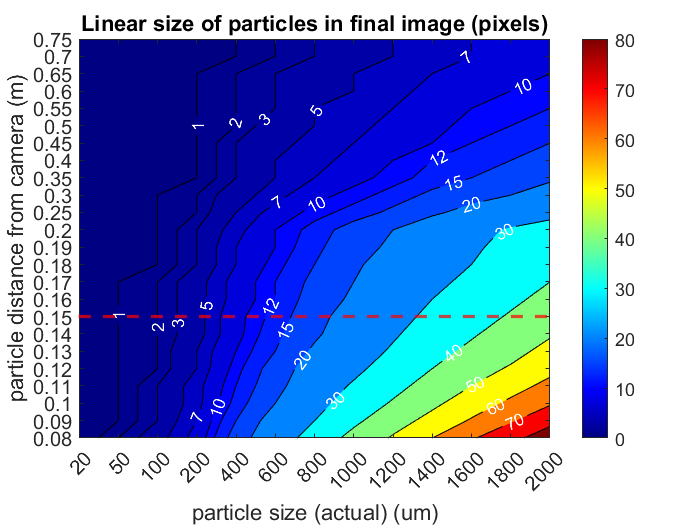

%calculate this equation for each particle size and then each distance the
%particle could be away
objectSizes = zeros(size(particleDistances,2),size(particleSizes,2));
for i =1:size(particleDistances,2)
    for j = 1:size(particleSizes,2)
        objectSizes(i,j) = (camera.focal_distance*particleSizes(j)*camera.resolution(2))/(particleDistances(i)*camera.sensor_size(2));
    end
end

%plot it
figure(1)
clf
[C,h] = contourf(floor(objectSizes),[-1 0 1 2 3 5 7 10 12 15 20:10:80]);
clabel(C,h,'Color','white');
yline(8,'r--', 'LineWidth', 2)
colormap("jet")
colorbar
yticks(1:1:24);
yticklabels(string(particleDistances));
xticks(1:1:13);
xticklabels(string(particleSizes*1000000));
xlabel('particle size (actual) (um)');
ylabel('particle distance from camera (m)');
title("Linear size of particles in final image (pixels)")
set(gca,'fontsize',12)

#### Calculate the depth of field given the lens and fov and f-stop

%set the acceptable circle of confusion as three pixels for the near DOF, for
%the far DOf we will be imaging larger particles so the circle of confusion
%can be somewhat larger
circleConfNear = 3*camera.pixel_size

circleConfNear = 4.6500e-06

circleConfFar = 4.5*camera.pixel_size

circleConfFar = 6.9750e-06


%set the working distance to approx 15cm
workingDistance =  0.15;

%create the symbolic equations
syms N f c D

%front Dof
Doffront = ((N*c*D)*(D - f))/(f^2 + N*c*(D - f))

$$Doffront = \frac{\text{D}\,N\,c\,\left(\text{D}-f\right)}{f^{2}+N\,c\,\left(\text{D}-f\right)}$$

%rear Dof
Dofrear = ((N*c*D)*(D - f))/(f^2 - N*c*(D - f))

$$Dofrear = \frac{\text{D}\,N\,c\,\left(\text{D}-f\right)}{f^{2}-N\,c\,\left(\text{D}-f\right)}$$

%calculate the f number by taking the focal length over aperture diameter
%get the aperture diamater by using the original focal length

%substitute to get:
%near depth of field
frontDof = eval(subs(Doffront,[N f c D],[camera.f_stop camera.focal_distance circleConfNear workingDistance]))

frontDof = 0.0236


%far depth of field
rearDof = eval(subs(Dofrear,[N f c D],[camera.f_stop camera.focal_distance circleConfFar workingDistance]))

rearDof = 0.0583


%total depth of field
totalDof = frontDof + rearDof

totalDof = 0.0818

%the volume calculation in liters
Rclose = (workingDistance-rearDof)*tand(camera.fov(2)*0.5);
Rfar = (workingDistance+frontDof)*tand(camera.fov(2)*0.5);
sharpImagingVolume = pi*totalDof*0.333*(Rfar^2 + Rclose*Rfar + Rclose^2)

sharpImagingVolume = 8.9724e-04

#### How many particles will we see and how fast will they appear to be moving

%get the flux through the volume per period of time
syms numParticles particleSpeed topSurfaceArea particleDensity

numParticles = particleSpeed*topSurfaceArea*particleDensity

$$numParticles = \mathrm{particleSpeed}\,\mathrm{particleDensity}\,\mathrm{topSurfaceArea}$$


%period of time we want to measure (hours)
periodOfTime = 1;

%the top surface of the sampling volume area
topSurfArea = (Rclose*2 + Rfar*2)*0.5*(totalDof)

topSurfArea = 0.0095

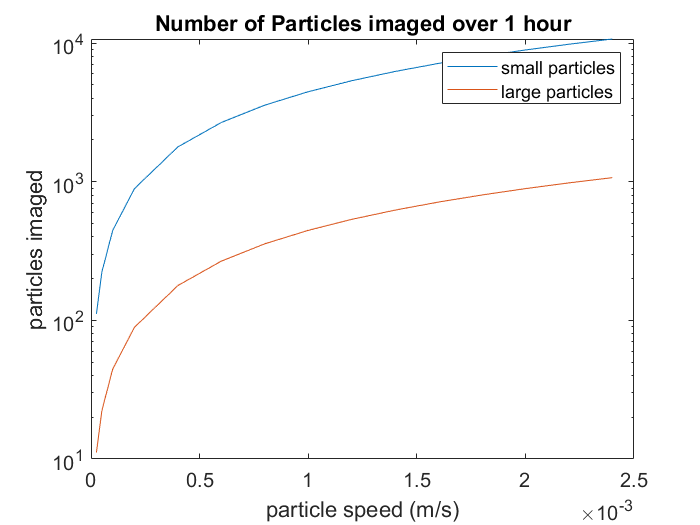

%note that we will only see small particles in the first 10-15% of the
%imaged volume as they need to be close to the camera to be imaged
%number of small particles
smallParticleNumber = particleSpeeds*topSurfArea*0.1*phytoDensity*60*60;

%large particel flow rate
largeParticleNumber = particleSpeeds*topSurfArea*mesoDensity*60*60;

%plot the particle numbers 
figure(8)
plot(particleSpeeds,10*smallParticleNumber,particleSpeeds,10*largeParticleNumber);
title("Number of Particles imaged over "+ string(periodOfTime) +" hour");
xlabel("particle speed (m/s)");
ylabel("particles imaged");
legend("small particles","large particles");
set(gca,'fontsize',12)
set(gca, 'YScale', 'log')

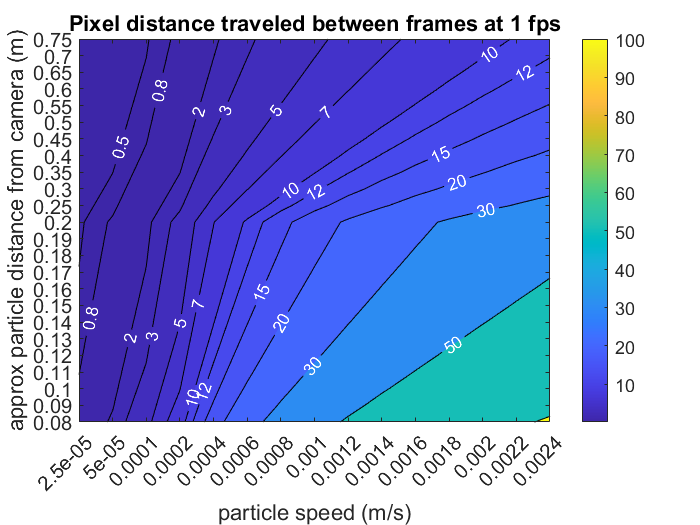

%now get the particle pixel speeds
%the camera frame rate 
frameRate = 1;

%the particle distances moved
particleVertDist = (1/frameRate)*particleSpeeds;

pixelDistances = zeros(size(particleDistances,2),size(particleVertDist,2));
for i =1:size(particleDistances,2)
    for j = 1:size(particleVertDist,2)
        pixelDistances(i,j) = (camera.focal_distance*particleVertDist(j)*camera.resolution(2))/(particleDistances(i)*camera.sensor_size(2));
    end
end


figure(7)
clf
[C,h] = contourf(pixelDistances,[-1 0.1 0.5 0.8 2 3 5 7 10 12 15 20 30 50 100 200:200:1000]);
clabel(C,h,'Color','white');
colormap("parula")
colorbar
yticks(1:1:24);
yticklabels(string(particleDistances));
xticks(1:1:15);
xticklabels(string(particleSpeeds));
xlabel('particle speed (m/s)');
ylabel('approx particle distance from camera (m)');
title("Pixel distance traveled between frames at " + string(frameRate) + " fps")
set(gca,'fontsize',12)

#### Calculate the Stereo-Camera overlap given the camera distances, angles and working distances

%first calculate the maximum overlap area between the stereo-cameras using
%a constrained search, write a basic function to find the overlap areas
%the distance between the cameras, maximize the distance between the
%cameras and maximize the area

%now given the parameters calculate the overlap volume and minimize the
%function
awns = fmincon(@(x) stereo_overlap(x,camera.fov(2)*0.5,frontDof,rearDof,workingDistance), [0.2,60],[],[],[],[],[0.03 22],[0.1 80])


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


awns =     0.0999   72.6316


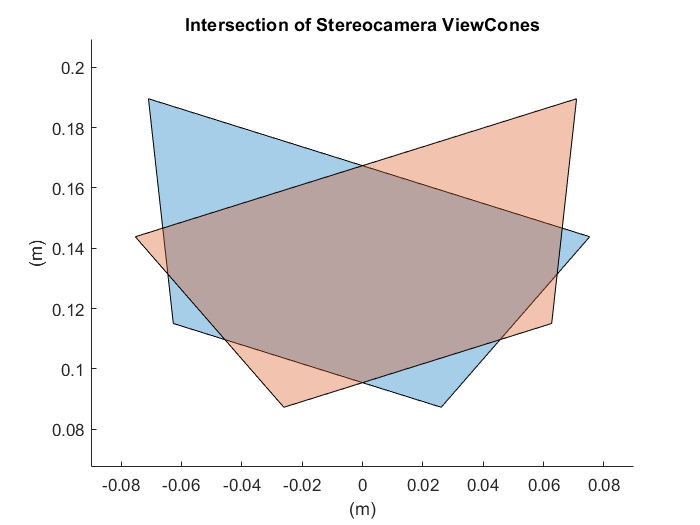

%plot the final overlap
%set the extra variables
distBetween = awns(1);
thetaHoriz = awns(2);
hFov = camera.fov(2)*0.5;
nearDof = frontDof;
farDof = rearDof;
wrkDist = workingDistance;

%the left camera position
cPosLeft = [-distBetween/2,0];

%the right camera position
cPosRight = [distBetween/2,0];

%the set of vectors for the left camera
%left most vector and right vector of the left camera
%and the center vectors showing the near and far dof
v1 = [cosd(thetaHoriz + hFov), sind(thetaHoriz + hFov)];
v2 = [cosd(thetaHoriz - hFov), sind(thetaHoriz - hFov)];
v5 = (wrkDist - nearDof)*[cosd(thetaHoriz), sind(thetaHoriz)];
v6 = (wrkDist + farDof)*[cosd(thetaHoriz), sind(thetaHoriz)];

%the set of vectors for the right camera
%right most vector and left vector of the right camera
%and the center vectors showing the near and far dof
v3 = [-cosd(thetaHoriz + hFov), sind(thetaHoriz + hFov)];
v4 = [-cosd(thetaHoriz - hFov), sind(thetaHoriz - hFov)];
v7 = (wrkDist - nearDof)*[-cosd(thetaHoriz), sind(thetaHoriz)];
v8 = (wrkDist + farDof)*[-cosd(thetaHoriz), sind(thetaHoriz)];

%using dot products, get the points which enclose the fields of view of
%the cameras
%left camera points
p1 = ((dot(v5,v1)/dot(v1,v1))*v1) + cPosLeft;
p2 = ((dot(v5,v2)/dot(v2,v2))*v2) + cPosLeft;
p3 = ((dot(v6,v1)/dot(v1,v1))*v1) + cPosLeft;
p4 = ((dot(v6,v2)/dot(v2,v2))*v2) + cPosLeft;

%right camera points
p5 = ((dot(v7,v4)/dot(v4,v4))*v4) + cPosRight;
p6 = ((dot(v7,v3)/dot(v3,v3))*v3) + cPosRight;
p7 = ((dot(v8,v4)/dot(v4,v4))*v4) + cPosRight;
p8 = ((dot(v8,v3)/dot(v3,v3))*v3) + cPosRight;

%create the polyshapes
c1 = polyshape([p1(1) p2(1) p4(1) p3(1)], [p1(2) p2(2) p4(2) p3(2)]);
c2 = polyshape([p5(1) p6(1) p8(1) p7(1)], [p5(2) p6(2) p8(2) p7(2)]);

%plot the intersection
figure(8)
clf
hold on
plot(c1)
plot(c2)
title("Intersection of Stereocamera ViewCones")
xlabel('(m)')
ylabel('(m)')
axis equal
hold off

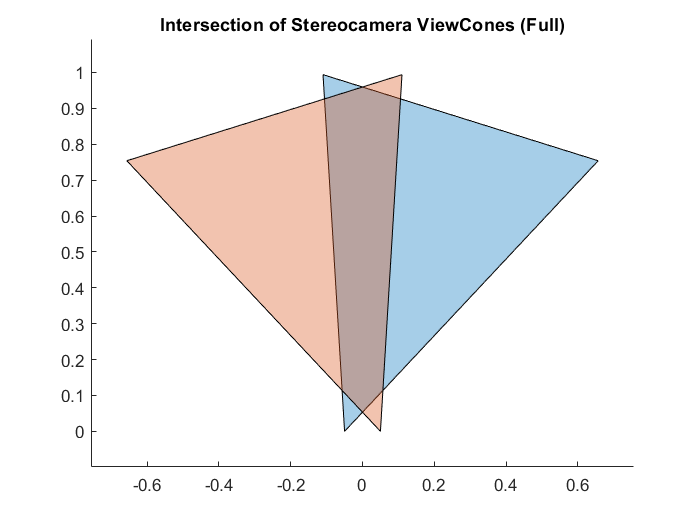

%get the ratio of the intersection volume to the total intersection volume
%create the new full viewcone shapes
c3 = polyshape([cPosLeft(1) v1(1)*1 v2(1)*1], [cPosLeft(2) v1(2)*1 v2(2)*1]);
c4 = polyshape([cPosRight(1) v3(1)*1 v4(1)*1], [cPosLeft(2) v3(2)*1 v4(2)*1]);

%plot the intersection
figure(9)
clf
hold on
plot(c3)
plot(c4)
title("Intersection of Stereocamera ViewCones (Full)")
axis equal
hold off

%the ratio of the intersection of the cut viewcones to the full viewcones
areaRatio = area(intersect(c1,c2))/area(intersect(c3,c4))

areaRatio = 0.0460



%calculate the volume of the cone overlap, first write it symbolically
%distance to intersection, angle a (half fov), viewcone skew angle
syms d a b
volCones = (4/3)*((d^3*a^3)/(1-a^2*b^2))*( ((a*(1+b^2)*sqrt(b^2-a^2))/(b^2*(1+a^2)^2)) + (1/(sqrt(1 -a^2*b^2)))*atand((a*(1+b^2))/(sqrt((b^2-a^2)*(1-a^2*b^2)))) )

$$volCones = \begin{array}{l} -\frac{4\,a^{3}\,d^{3}\,\left(\frac{180\,\mathrm{atan}\left(\frac{a\,\left(b^{2}+1\right)}{\sqrt{\left(a^{2}-b^{2}\right)\,\left(\sigma_{1}-1\right)}}\right)}{\pi \,\sqrt{1-\sigma_{1}}}+\frac{a\,\left(b^{2}+1\right)\,\sqrt{b^{2}-a^{2}}}{b^{2}\,{\left(a^{2}+1\right)}^{2}}\right)}{3\,\left(\sigma_{1}-1\right)}\\ \mathrm{where}\\ \sigma_{1}=a^{2}\,b^{2} \end{array}$$

%now plug in the values for a, b and d
aActual = tand(camera.fov(2)*0.5);
bActual = tand(thetaHoriz);
dist = distBetween/(2*cosd(thetaHoriz));

%now plug in and get the total volume of the cone intersection
totalVolume = abs(eval(subs(volCones,[d a b], [dist aActual bActual])))*100

totalVolume = 5.5036

%now get the volume of the stereocamera intersection (very roughly) in m
%cubed
intersectionVolume = areaRatio*totalVolume

intersectionVolume = 0.2531

#### Calculate the Lighting required to illuminate a range of particles to a certain degree

% %figure out the cross sectional area and amount of light shone on thet area
% %from four lights (assuming the hemispherical nature of light spread), the
% %using a distribution of particle distances and brightnesses, figure out
% %the ideal brightness for the lights by looking for the lightness values of
% %particles inside the depth of field
% 
% %the number of LEDs we are calculating for
% numLEDs = 1;
% 
% %create a symbolic variable for the power of a single LED in luminous
% %intensity
% ledPwr = 53/683;
% 
% %the angle at which the LED light will subtend, make it 20 percent greater
% %than the camera FOV
% ledLightAngle = camera.fov(2)*0.5*1.2;
% 
% %get the total area the light subtends at the working distance
% surfArea = pi*(workingDistance*sind(ledLightAngle))^2
% 
% %get the area of particle the light is shining upon and divide by total
% %area to get ratio of intensity of light the particle will reflect
% areaSubtended = particleSizes(2)^2;
% 
% %get the area ratio 
% areaRatio = particleSizes(2)^2/surfArea
% 
% %now get the number of watts of brightness over the particle region
% rawBrightness = numLEDs*ledPwr*areaRatio
% 
% %now we can track the "ray" of light, and take into account attenuation,
% %scattering and the reflectance of the object, the way it goes is:
% %rawBrightness -> -absorbtion - scattering -> reflection ->  -more absorbtion
% % - scattering + backscattering -> lens brightness reduction -> sensor efficiency
% 
% %some percentage reflectance by each particle
% particleReflectances = [0.01 0.02 0.05:0.05:0.2 0.25:0.1:0.55];
% 
% %the attenuation coefficient, use the coefficients at 470 nm
% %basic attenuation coeff, scattering coeff and additional coeff for 
% %additional particulates
% attenuationCoeff = 0.0156 + 0.0037 + 0.005
% %the scattering coeff, use a small value, this is VERY dependent on what
% %kind of particles are in the water
% backscatterCoeff = 46e-10;
% 
% %the direct reflectance, multiply by the width of the particle here and get
% %a super small value 
% brightnessDirect = rawBrightness*particleReflectances*exp(-1*workingDistance*2*attenuationCoeff)*1e-3
% 
% %the scattered light component at this point ignore because this may be the
% %light we are trying to get...
% brightnessScattered = 0 %rawBrightness*exp(-workingDistance*backscatterCoeff)
% 
% %now we get the total brightness 
% totalIncomingBrightness = brightnessScattered + brightnessDirect
% 
% %now take the light and multiply by lens efficiency then by exposure time
% %to get the power on a pixel
% 
% %exposure time
% exposureT = 0.0005;
% 
% %lens efficiency
% lensEff = 0.8;
% 
% %power onto the pixel, divide by three as three pixels will share the light
% pwrIntoPix = exposureT*totalIncomingBrightness*lensEff*0.33;
% 
% %watts per photon
% wattsPerPhoton = (6.63e-34*3e8)/(470e-9)
% 
% %photons into the pixel
% photonIntoPix = pwrIntoPix/wattsPerPhoton
% 
% %quantum efficiency to get snr, or sqrt of maximum saturation capactiy of
% %electrons...
% pixSNR = sqrt(photonIntoPix*0.4)

#### Calculate the lighting in a MORE COMPLICTED WAY

% %the number of LED lights
% snumLEDs = 1;
% 
% %distance between the led and camera (center)
% sdLed = 0.05;
% 
% %the distance from the particle to camera
% sworkDistance = workingDistance;
% 
% %get the angle between the particle and the led light to slightly decrease
% %the amount of light based on the LED datasheet
% sangleParticle = atand(sworkDistance/sdLed);
% 
% %the distance from LED to particle
% sdistParticle = sqrt(sworkDistance^2 + sdLed^2)
% 
% %the LED power we have for a single LED in watts, driving the RED led (625 nm) at
% %350mA, 2.1v so total driving power 0.73 watts, this is total power so
% %based on the light angle we will reduce the power and also convert from lumens
% %to watts
% snumLEDPWr = (56.8/180.995)*snumLEDs
% 
% %calculate the amount of light on a single particle, taking into account a
% %reduction by the attenuation due to absorbtion by seawater (ignore
% %scattering for now...)
% sradianceParticleNoAbs = snumLEDPWr * ((particleSizes(1)^2)/(sworkDistance^2))
% 
% %reduce by absorbtion plus albedo for initial light
% sirradiationParticle = sradianceParticleNoAbs*0.85*exp(-sdistParticle*0.319)
% 
% %now get the radiance of the particle( as hemisphere)
% sradianceParticle = sirradiationParticle/pi
% %now reduce by some more attenuation, divide by distance squared to get
% sirradiationIntoLens = sradianceParticle*exp(-sworkDistance*0.319)
% %calculate aperture size
% apertureSize = camera.focal_distance/camera.f_stop
% %use radiometric relation to get image Irradiance (on single pixel)
% %maybe??
% %(pi/4)*((apertureSize/camera.focal_distance)^2)*sirradiationIntoLens
% %or just do reverse of LED calculation
% spixIrradiance = sirradiationIntoLens*(pi*(apertureSize/2)^2)*(1/sworkDistance)
% %multiply by exposure time and lens efficiency to get the POWER
% spowerIntoPix = 0.008*0.8*spixIrradiance
% %convert into photons
% sePhoton = ((6.62e-34)*(3e8))/(625e-9)
% %number of photons on a pixel
% snumPhotons = spowerIntoPix/sePhoton
% %get the SNR by using the quantum efficiency
% sSnr = sqrt(snumPhotons*0.6)


#### LIGHTING FINAL CALCULATIONS

%number of LEDs
numLeds = 1;

%power of LED as the number of W going into the hemisphere
ledPWR = 0.350;




#### Power Calculations

%for the ras pi and LEDs consuming power, and the esp32 as well (may be
%able to put this on a seperate smaller battery) how can we power them?

Stereo overlap function - distance between cameras,  half fov, camera angle to horizontal, near dof, far dof, working distance

function negArea = stereo_overlap(unknowns, hFov, nearDof, farDof, wrkDist)
    
    %set the unknown variables to optimize for
    d = unknowns(1);
    thetaHoriz = unknowns(2);
    
    %the left camera position
    cPosLeft = [-d/2,0];
    
    %the right camera position
    cPosRight = [d/2,0];
    
    %the set of vectors for the left camera
    %left most vector and right vector of the left camera
    %and the center vectors showing the near and far dof
    v1 = [cosd(thetaHoriz + hFov), sind(thetaHoriz + hFov)];
    v2 = [cosd(thetaHoriz - hFov), sind(thetaHoriz - hFov)];
    v5 = (wrkDist - nearDof)*[cosd(thetaHoriz), sind(thetaHoriz)];
    v6 = (wrkDist + farDof)*[cosd(thetaHoriz), sind(thetaHoriz)];
    
    %the set of vectors for the right camera
    %right most vector and left vector of the right camera
    %and the center vectors showing the near and far dof
    v3 = [-cosd(thetaHoriz + hFov), sind(thetaHoriz + hFov)];
    v4 = [-cosd(thetaHoriz - hFov), sind(thetaHoriz - hFov)];
    v7 = (wrkDist - nearDof)*[-cosd(thetaHoriz), sind(thetaHoriz)];
    v8 = (wrkDist + farDof)*[-cosd(thetaHoriz), sind(thetaHoriz)];
    
    %using dot products, get the points which enclose the fields of view of
    %the cameras
    %left camera points
    p1 = ((dot(v5,v1)/dot(v1,v1))*v1) + cPosLeft;
    p2 = ((dot(v5,v2)/dot(v2,v2))*v2) + cPosLeft;
    p3 = ((dot(v6,v1)/dot(v1,v1))*v1) + cPosLeft;
    p4 = ((dot(v6,v2)/dot(v2,v2))*v2) + cPosLeft;
    
    %right camera points
    p5 = ((dot(v7,v4)/dot(v4,v4))*v4) + cPosRight;
    p6 = ((dot(v7,v3)/dot(v3,v3))*v3) + cPosRight;
    p7 = ((dot(v8,v4)/dot(v4,v4))*v4) + cPosRight;
    p8 = ((dot(v8,v3)/dot(v3,v3))*v3) + cPosRight;
    
    %create the polyshapes
    c1 = polyshape([p1(1) p2(1) p4(1) p3(1)], [p1(2) p2(2) p4(2) p3(2)]);
    c2 = polyshape([p5(1) p6(1) p8(1) p7(1)], [p5(2) p6(2) p8(2) p7(2)]);

    %get the area of the intersection and negate for purposes of
    %minimization, multiply by d to maximize stereo distance
    negArea = -1*area(intersect(c1,c2))*d;
end
